# Respuesta al escalón unitario para un sistema LTI de segundo orden en tiempo continuo

Definición del vector de tiempo, desde 0 hasta T segundos

T=30; %segundos
tsim=0.01;
t=0:tsim:T;

Valores de los parámetros del sistema según la ecuación diferencial descrita en el documento de la tarea correspondiente

m=30;
b=20;
k=50;

Cálculo de las constantes para la función de transferencia

b1=b/m;
a1=b1;
b2=k/m;
a2=b2;
num=[0 b1 b2];
den=[1 b1 b2];

Generación de la respuesta al escalón unitario del sistema

[y]=step(num,den,t);
figure
plot(t,y)

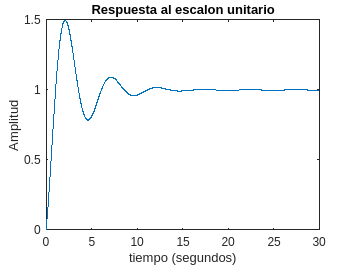

xlabel('tiempo (segundos)')
ylabel('Amplitud')
title('Respuesta al escalon unitario')

**Muestreo de la respuesta al escalón unitario del sistema LTI** 

Se obtienen los valores del muestreo a partir de los valores de la señal de tiempo continuo, aun se sigue representando la señal en segundos.

Ns=100; %Factor de sub-muestreo
nTs=t(1:Ns:length(t));
yTs=y(1:Ns:length(y));
fprintf('Periodo de muestreo: %4.2f segundos',nTs(2))

Periodo de muestreo: 1.00 segundos

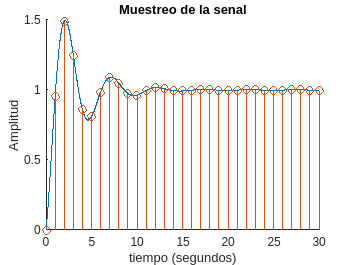

figure
hold on
plot(t,y)
stem(nTs,yTs)
xlabel('tiempo (segundos)')
ylabel('Amplitud')
title('Muestreo de la senal')
hold off

**Representación de la señal de tiempo discreto**

Observe la variable de tiempo, ya no representa segundos sino muestras.

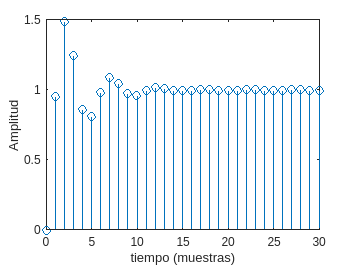

N=length(nTs);
n=0:N-1;
figure
stem(n,yTs)
xlabel('tiempo (muestras)')
ylabel('Amplitud')

title('Senal discretizada')